# Simulation of scenarios

clear;clc;close all
T=readtable('Dane/anexo-proyecciones-poblacion-Nacional2018_2070.xlsx');

Tman=T{3:3:159,6:100+4};
Tman(:,end+1)=sum(T{3:3:159,105:106},2);
Twoman=T{3:3:159,107:107+98};
Twoman(:,end+1)=sum(T{3:3:159,205:206},2);
Tpob=Tman+Twoman;
T2=readtable('Dane/proyecciones-nivel-nacional-departamental-por-sexo-y-edades-simples-hasta-80-anos-y-mas.xls');

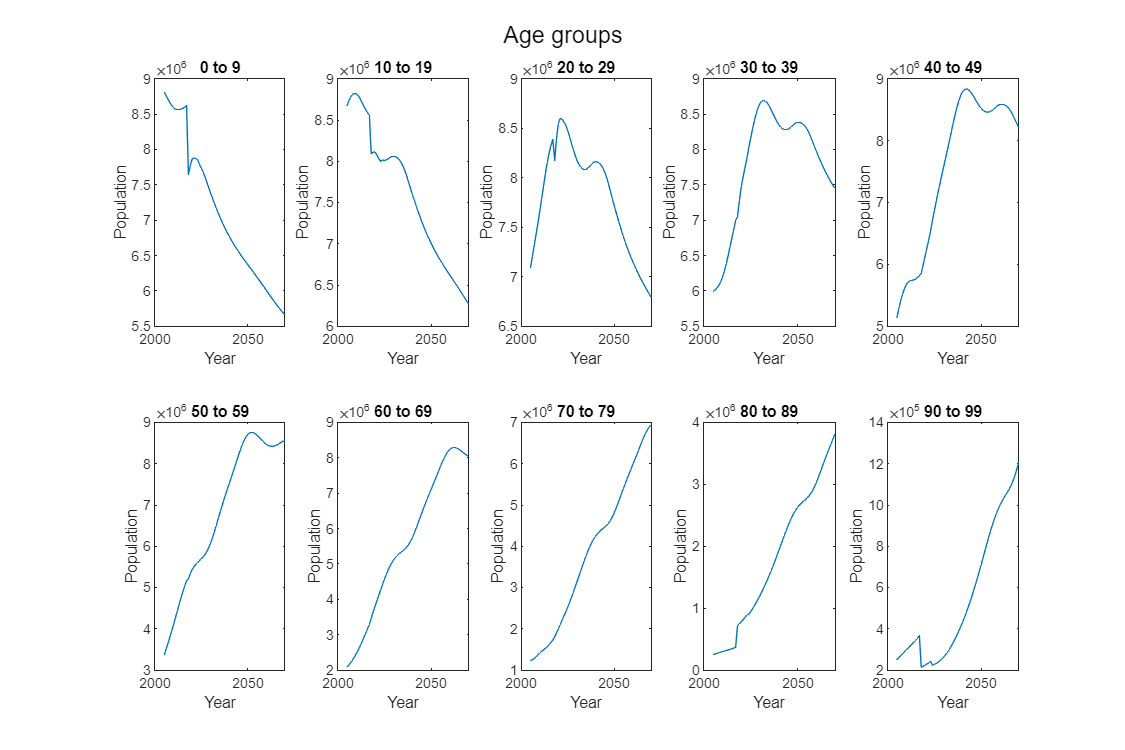

Tinfo=T2{1:13,7:87};
Tpast=[Tinfo(:,1:80), repmat(Tinfo(:,end)/20,1,20)];
Tpob = [Tpast;Tpob];

[nciclos,~]=size(Tpob);

year_transM=zeros(100,100);
for i=1:99
    year_transM(i,i+1)=1;
end
out_ge_matrix=zeros(100,10);
for i=1:10
    out_ge_matrix((i-1)*10+1:i*10,i)=1;
end
summ_pob=Tpob*out_ge_matrix;

 
figure('Renderer', 'painters', 'Position', [10 10 900 600])
clf
ge_names = {'0 to 9','10 to 19','20 to 29','30 to 39','40 to 49','50 to 59',...
    '60 to 69','70 to 79','80 to 89','90 to 99'};
time=2005:2005+nciclos-1;
for i=1:10
    subplot(2,5,i)
    plot(time,summ_pob(:,i))
    xlabel('Year')
    ylabel('Population')
    title(ge_names{i})
end
sgtitle('Age groups')

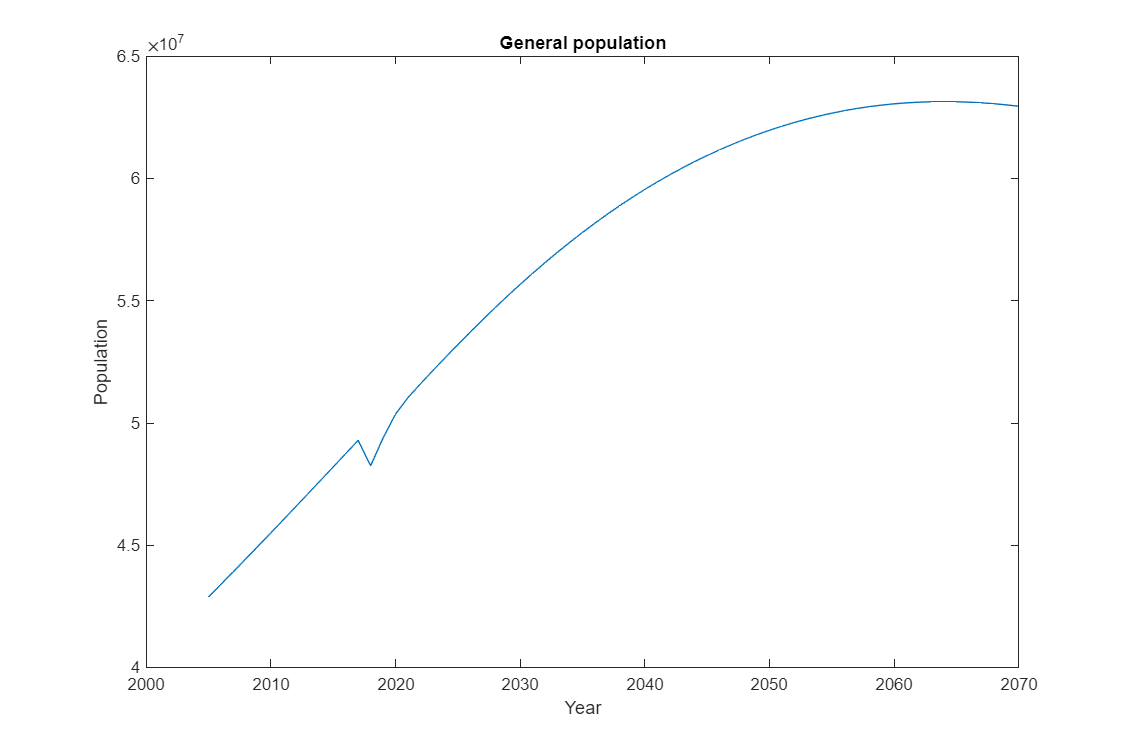

figure('Renderer', 'painters', 'Position', [10 10 900 600])
clf
plot(time,sum(summ_pob,2));
xlabel('Year')
ylabel('Population')
title('General population')

### Disease parameterization

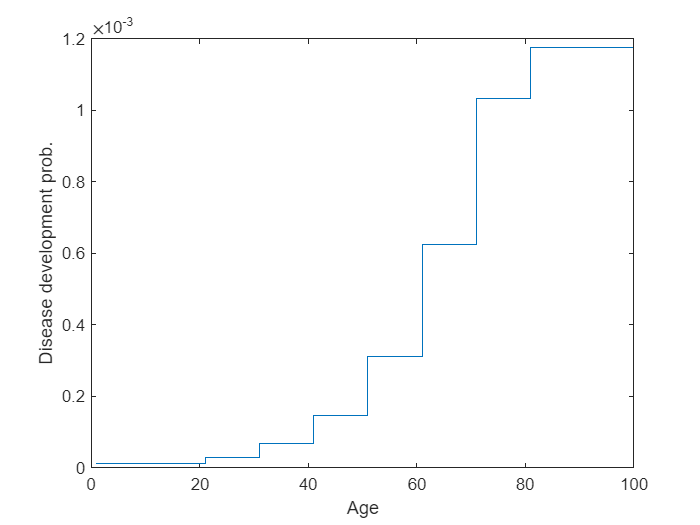

pob_det=Tpob;
i1=14.6; i2=13.9; i3=34.2; i4=81.3; i5=175.4; i6=374.3; i7=749.1; i8=1239.4; i9=1412.2; i10=1412.2;
betafunill=[repmat(i1,1,10) repmat(i2,1,10) repmat(i3,1,10) repmat(i4,1,10)...
    repmat(i5,1,10) repmat(i6,1,10) repmat(i7,1,10) repmat(i8,1,10) repmat(i9,1,10)...
    repmat(i10,1,10)]/(1e5*12);

figure(5)
clf
stairs(betafunill)
xlabel("Age")
ylabel("Disease development prob.")

### Simulation time settings

ciclo_externo=66;
ciclo_interno=12;
limit_start=nciclos-ciclo_externo;
xtime1 = datetime(2019,1,1,0,0,0);
xtime2 = datetime(2018+ciclo_externo,1,1,0,0,0);
xtime = xtime1:calmonths(12/ciclo_interno):xtime2;

start=1;
start2=19;
input_matrix = struct();
input_matrix.poblacion=Tpob;
input_matrix.year_transM=year_transM;
input_matrix.out_ge_matrix=out_ge_matrix;

### Treatment and detection settings

det_prob=[0.1422,0.2525,0.3489,1];%Probabilidad de detección en cada fase

Probabilidad de recibir tratamiento dado la fase


$$\textrm{Tipo}\;\textrm{Contrato}\times \textrm{fase}=\left\lbrack \begin{array}{cccc}
0\ldotp 7 & 0\ldotp 6 & 0\ldotp 4 & 0\ldotp 1\\
0\ldotp 2 & 0\ldotp 3 & 0\ldotp 4 & 0\ldotp 4\\
0\ldotp 1 & 0\ldotp 1 & 0\ldotp 2 & 0\ldotp 5
\end{array}\right\rbrack$$


det_cost=916000;
%trat prob estimada
%trat_prob=[0.9 0.4618 0.9 0.1; 0.9 0.1 0.1 0.1;0.59496 0.59496 0.59496 0.59496]; 
%trat prob inferida
trat_prob=[0.196 0.196 0.196 0.196; 0.26 0.26 0.26 0.26;0.59496 0.59496 0.59496 0.59496];
%trat_prob hipotesis
%trat_prob=[0 0 0 0; 0.6916 0.6916 0.6916 0.6916;1 1 1 1]; 

Efectividad del tratamiento dada la fase


$$\textrm{Efectividad}\;\textrm{Contrato}\times \textrm{fase}=\left\lbrack \begin{array}{cccc}
0\ldotp 8 & 0\ldotp 7 & 0\ldotp 5 & 0\ldotp 2\\
0\ldotp 9 & 0\ldotp 8 & 0\ldotp 6 & 0\ldotp 4\\
0\ldotp 95 & 0\ldotp 85 & 0\ldotp 7 & 0\ldotp 5
\end{array}\right\rbrack$$


%efectividad sin threshold
efect_trat=[0.0882 0.1413 0.2042 0.1217;0.0697 0.186 0.1639 0.181;0.0314 0.2733 0.0761 0.25];
%efectividad con threshold
%efect_trat=[0.0882 0.1413 0.2042 0.1217;0.0882 0.1469 0.2042 0.1726;0.0882 0.1603 0.2042 0.2107];

Costo del tratamiento dada la fase


$$\textrm{Costo}\;\textrm{Contrato}\times \textrm{fase}=\left\lbrack \begin{array}{cccc}
1 & 2 & 3 & 4\\
2 & 3 & 4 & 5\\
3 & 4 & 5 & 6
\end{array}\right\rbrack$$


%cost_trat=[1.88E+07 1.97E+07 2.83E+08 2.58E+08; 2.35E+07 2.47E+07 3.29E+08 3.66E+08; 1.59E+07 3.17E+07 3.81E+08 4.76E+08]/12;
%costo paper
cost_trat=[8.97E+06 4.76E+07 5.60E+07 1.09E+08; 9.39E+06 5.19E+07 6.39E+07 1.44E+08; 1.21E+07 8.14E+07 1.04E+08 1.49E+08]/12;

Probabilidad de cambio de fase dado el tratamiento y la fase


$$\textrm{Contrato}\times \textrm{fase}=\left\lbrack \begin{array}{cccc}
0\ldotp 5 & 0\ldotp 5 & 0\ldotp 6 & 0\ldotp 7\\
0\ldotp 5 & 0\ldotp 5 & 0\ldotp 6 & 0\ldotp 7\\
0\ldotp 5 & 0\ldotp 5 & 0\ldotp 6 & 0\ldotp 7
\end{array}\right\rbrack$$


%progreso sin threshold
prog_fase=[0.6398 0.6535 0.5479 0.2296 0.6398 0.6532 0.5479 0.1724 0.6398 0.6532 0.5479 0.1135];
%progreso con threshold
%prog_fase=[0.6398 0.6532 0.5479 0.2296 0.6398 0.6532 0.5479 0.1704 0.6398 0.6532 0.5479 0.1017];
pfase_nt=[0.6398 0.6532 0.5479];%Probabilidad de cambio de fase sin tratamiento
trans=[0.2 0.2];
improvement=0;
early=0.0874;
early_cost=0;

Los parámetros que pueden cambiarse son

- Costos de tratamientos (1 param)

- Probabilidad de tipo de tratamiento

nominal = [det_prob(1),det_prob(2),det_prob(3),det_prob(4),...
    trat_prob(1,1),trat_prob(2,1),trat_prob(3,1),trat_prob(1,2),...
    trat_prob(2,2),trat_prob(3,2),trat_prob(1,3),trat_prob(2,3),...
    trat_prob(3,3),trat_prob(1,4),trat_prob(2,4),trat_prob(3,4),...
    efect_trat(1,1),efect_trat(2,1),efect_trat(3,1),efect_trat(1,2),...
    efect_trat(2,2),efect_trat(3,2),efect_trat(1,3),efect_trat(2,3),...
    efect_trat(3,3),efect_trat(1,4),efect_trat(2,4),efect_trat(3,4),...
    cost_trat(1,1),cost_trat(2,1),cost_trat(3,1),cost_trat(1,2),...
    cost_trat(2,2),cost_trat(3,2),cost_trat(1,3),cost_trat(2,3),...
    cost_trat(3,3),cost_trat(1,4),cost_trat(2,4),cost_trat(3,4),...
    prog_fase(1),prog_fase(2),prog_fase(3),prog_fase(4),prog_fase(5),...
    prog_fase(6),prog_fase(7),prog_fase(8),prog_fase(9),prog_fase(10),...
    prog_fase(11),prog_fase(12),pfase_nt(1),pfase_nt(2),pfase_nt(3),...
    det_cost,start2,trans(1),trans(2),improvement,early, early_cost,...
    det_prob(1),det_prob(2),det_prob(3),det_prob(4),...
    trat_prob(1,1),trat_prob(2,1),trat_prob(3,1),trat_prob(1,2),...
    trat_prob(2,2),trat_prob(3,2),trat_prob(1,3),trat_prob(2,3),...
    trat_prob(3,3),trat_prob(1,4),trat_prob(2,4),trat_prob(3,4),...
    efect_trat(1,1),efect_trat(2,1),efect_trat(3,1),efect_trat(1,2),...
    efect_trat(2,2),efect_trat(3,2),efect_trat(1,3),efect_trat(2,3),...
    efect_trat(3,3),efect_trat(1,4),efect_trat(2,4),efect_trat(3,4),...
    cost_trat(1,1),cost_trat(2,1),cost_trat(3,1),cost_trat(1,2),...
    cost_trat(2,2),cost_trat(3,2),cost_trat(1,3),cost_trat(2,3),...
    cost_trat(3,3),cost_trat(1,4),cost_trat(2,4),cost_trat(3,4),...
    prog_fase(1),prog_fase(2),prog_fase(3),prog_fase(4),prog_fase(5),...
    prog_fase(6),prog_fase(7),prog_fase(8),prog_fase(9),prog_fase(10),...
    prog_fase(11),prog_fase(12),pfase_nt(1),pfase_nt(2),pfase_nt(3),...
    det_cost,early, early_cost,0.642];
ParNames =  {'df1','df2','df3','df4', 'tr1f1', 'tr2f1','tr3f1','tr1f2',...
'tr2f2','tr3f2','tr1f3','tr2f3','tr3f3','tr1f4','tr2f4','tr3f4','efT1f1',...
'efT2f1','efT3f1','efT1f2','efT2f2','efT3f2','efT1f3','efT2f3','efT3f3',...
'efT1f4','efT2f4','efT3f4','csT1f1','csT2f1','csT3f1','csT1f2','csT2f2',...
'csT3f2','csT1f3','csT2f3','csT3f3','csT1f4','csT2f4','csT3f4','prT1f1',...
'prT1f2','prT1f3','prT1f4','prT2f1','prT2f2','prT2f3','prT2f4','prT3f1',...
'prT3f2','prT3f3','prT3f4','prNf1','prNf2','prNf3','dCost','brP','trans1',...
'trans2','impr', 'early','earlyC', ...
'Cdf1','Cdf2','Cdf3','Cdf4', 'Ctr1f1', 'Ctr2f1','Ctr3f1','Ctr1f2',...
'Ctr2f2','Ctr3f2','Ctr1f3','Ctr2f3','Ctr3f3','Ctr1f4','Ctr2f4','Ctr3f4','CefT1f1',...
'CefT2f1','CefT3f1','CefT1f2','CefT2f2','CefT3f2','CefT1f3','CefT2f3','CefT3f3',...
'CefT1f4','CefT2f4','CefT3f4','CcsT1f1','CcsT2f1','CcsT3f1','CcsT1f2','CcsT2f2',...
'CcsT3f2','CcsT1f3','CcsT2f3','CcsT3f3','CcsT1f4','CcsT2f4','CcsT3f4','CprT1f1',...
'CprT1f2','CprT1f3','CprT1f4','CprT2f1','CprT2f2','CprT2f3','CprT2f4','CprT3f1',...
'CprT3f2','CprT3f3','CprT3f4','CprNf1','CprNf2','CprNf3','CdCost', 'Cearly', 'CearlyC', 'desfC'};
VarNames = {};
OutNames = {'EnfDf1','EnfDf2','EnfDf3','EnfDf4','EnfNDf1','EnfNDf2','EnfNDf3',...
    'EnfNDf4','Rf1','Rf2','Rf3','Rf4','RfT','Gasf1','Gasf2','Gasf3','Gasf4','GasT',...
    'Dead','EnfDT','EnfNDT','DeadG1','DeadG2','DeadG3','DeadG4','DeadG5','DeadG6',...
    'DeadG7','DeadG8','DeadG9','DeadG10','EnfDG1','EnfDG2','EnfDG3','EnfDG4','EnfDG5','EnfDG6',...
    'EnfDG7','EnfDG8','EnfDG9','EnfDG10','EnfNDG1','EnfNDG2','EnfNDG3','EnfNDG4','EnfNDG5','EnfNDG6',...
    'EnfNDG7','EnfNDG8','EnfNDG9','EnfNDG10','EnfTr1F1','EnfTr1F2','EnfTr1F3','EnfTr1F4','EnfTr2F1',...
    'EnfTr2F2','EnfTr2F3','EnfTr2F4','EnfTr3F1','EnfTr3F4','EnfTr3F3','EnfTr3F4','CNR','rDead','rGasto','obj','pibGasto'};

FullNames = [VarNames,ParNames];
Range1 = [];


%Range2=[zeros(121,1),ones(121,1)]; todos los params
Range2 = [nominal',nominal'];
Range2([57:60,63:65,67:68,70,71,73,74,76,77,79:120],:) = [19 19;
    0 1; 0 5; -0.05 0.05;zeros(23,1) ones(23,1);
    nominal(91:102)'*0.5 nominal(91:102)'*1.5;
    zeros(15,1) ones(15,1);
    916000*0.5 916000*1.5;
    0 1;
    0 916000/120]; %params para estimar

RangeT = [Range1; Range2];

extra=struct();
extra.poblacion=pob_det';
extra.ciclo_interno=ciclo_interno;
extra.ciclo_externo=ciclo_externo;
extra.betafunill=betafunill;
extra.out_ge_matrix=out_ge_matrix;
extra.estC=1;

  T = gsua_dataprep("illnessGsua", RangeT, 'domain', [1 624],'nominal',nominal, 'names',...
        FullNames, 'out_names', OutNames,'opt', extra);

Setting environment to work with user-defined function


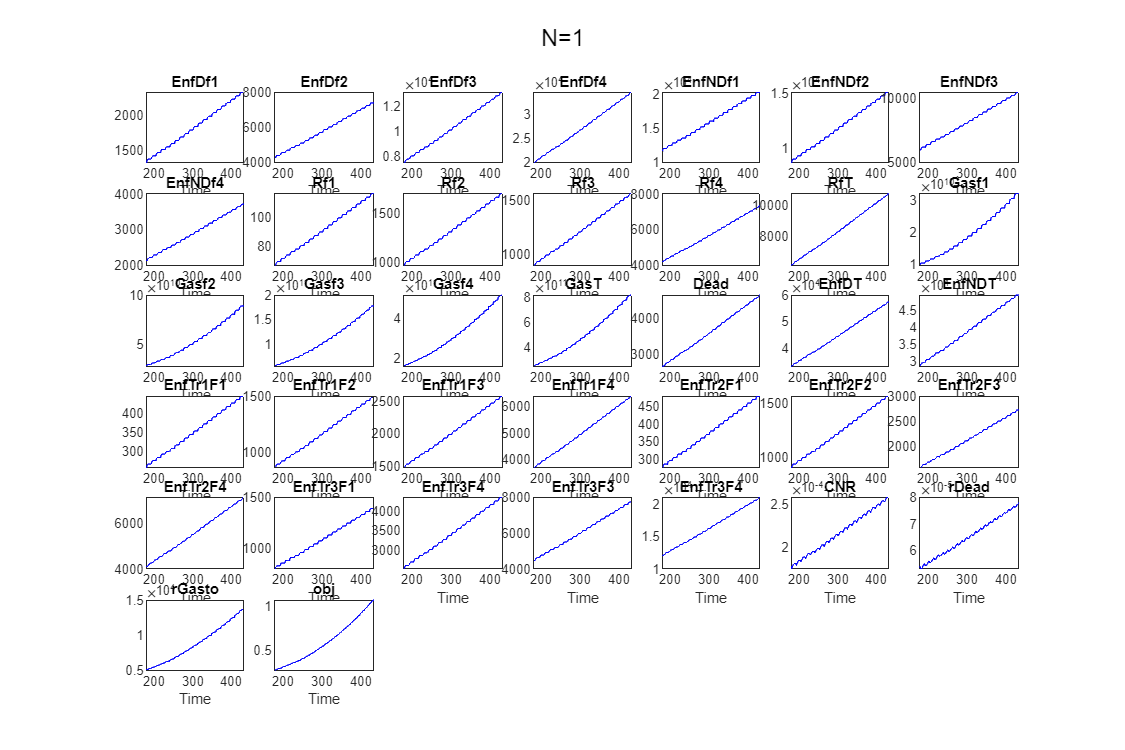

figure(1)
clf
T.Properties.CustomProperties.output=[1:21,52:67];
ydat=gsua_eval(T.Nominal,T,180:432);

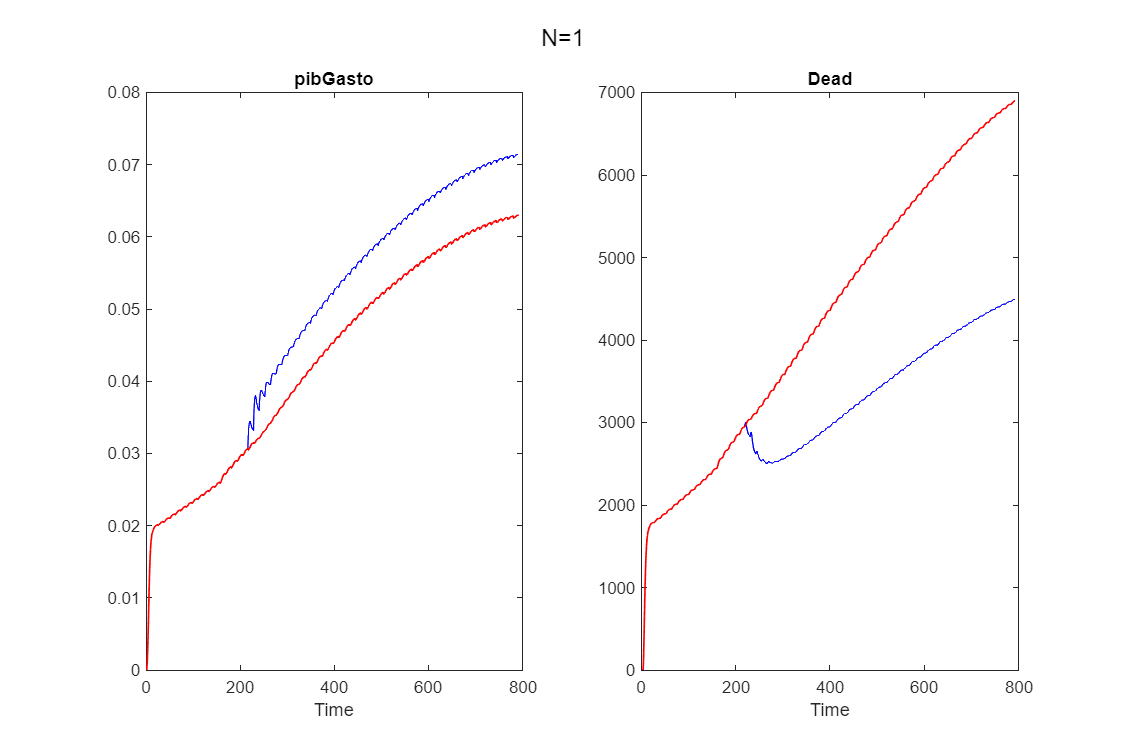

T.Properties.CustomProperties.output=[1:21,52:67];
%figure(1)
%clf
T.Ch=T.Nominal;
T{"Cearly","Ch"}=1;
% T{"Ctr1f1","Ch"}=0.1;
% T{"Ctr2f1","Ch"}=0.2;
% T{"CefT3f1","Ch"}=0.6;
% T{"CprT3f1","Ch"}=0.3;
T{"trans1","Ch"}=0.2;
T{"trans2","Ch"}=1;
%T{"Cdf2","Ch"}=T{"Cdf2","Nominal"}+0.1;
%y=gsua_eval(T.Ch,T,1:792,squeeze(ydat)');
figure(2)
clf
T.Properties.CustomProperties.output=[68,19];
ydat=gsua_deval([T.Nominal]',T,1:792);
y=gsua_eval([T.Ch],T,1:792,ydat);

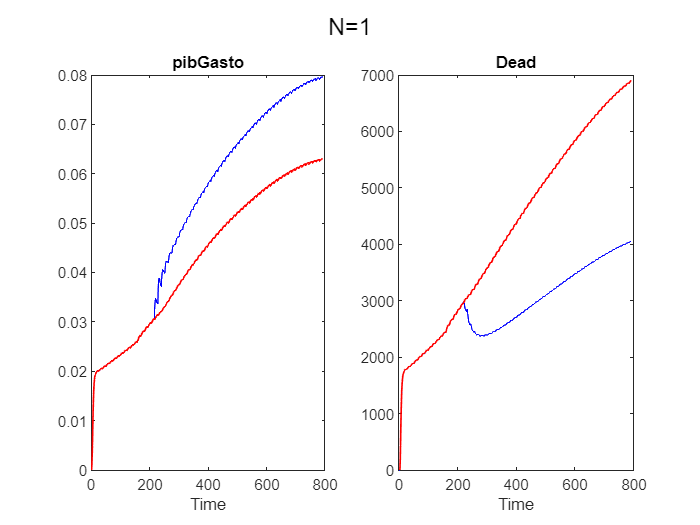

T{"Cearly","Ch"}=1;
T{"Ctr1f1","Ch"}=0.1;
T{"Ctr2f1","Ch"}=0.2;
% T{"CefT3f1","Ch"}=0.6;
% T{"CprT3f1","Ch"}=0.3;
T{"trans1","Ch"}=0.2;
T{"trans2","Ch"}=1;
figure(3)
clf
T.Properties.CustomProperties.output=[68,19];
y2=gsua_eval([T.Ch],T,1:792,ydat);

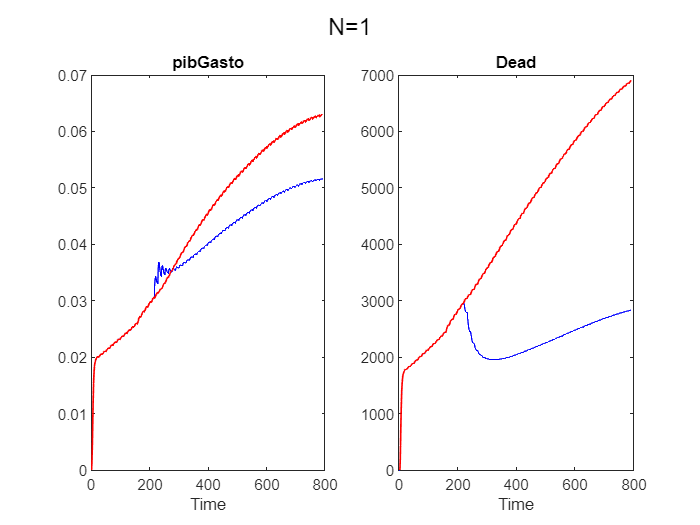

T{"Cearly","Ch"}=1;
T{"Ctr1f1","Ch"}=0.1;
T{"Ctr2f1","Ch"}=0.2;
T{"CefT3f1","Ch"}=0.6;
T{"CprT3f1","Ch"}=0.3;
T{"trans1","Ch"}=0.2;
T{"trans2","Ch"}=1;
figure(4)
clf
T.Properties.CustomProperties.output=[68,19];
y3=gsua_eval([T.Ch],T,1:792,ydat);

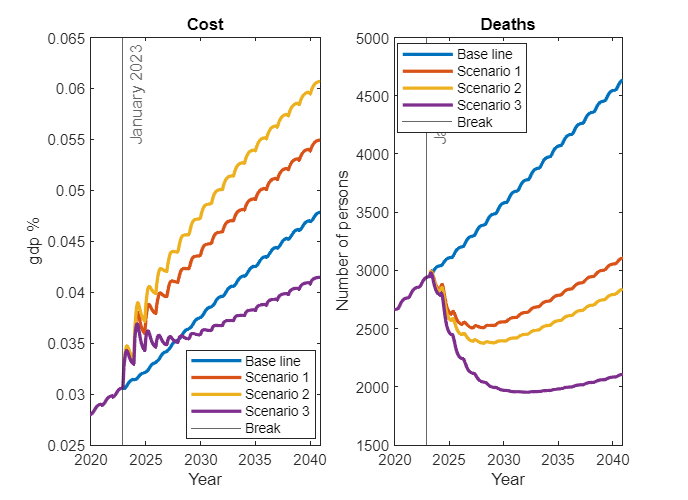

time2=datetime(2005,1,1):calmonths(1):datetime(2070,12,1);
figure(3)
clf
subplot(1,2,1)
plot(time2(180:432),ydat(1,180:432,1),'LineWidth',2)
hold on
plot(time2(180:432),y(1,180:432,1),'LineWidth',2)
plot(time2(180:432),y2(1,180:432,1),'LineWidth',2)
plot(time2(180:432),y3(1,180:432,1),'LineWidth',2)
 xline(time2(216),'-','January 2023')
 legend({'Base line','Scenario 1','Scenario 2','Scenario 3','Break'},'Location','best')
 title('Cost')
 xlabel('Year')
 ylabel('gdp %')
 subplot(1,2,2)
 plot(time2(180:432),ydat(2,180:432,1),'LineWidth',2)
hold on
plot(time2(180:432),y(1,180:432,2),'LineWidth',2)
plot(time2(180:432),y2(1,180:432,2),'LineWidth',2)
plot(time2(180:432),y3(1,180:432,2),'LineWidth',2)
 xline(time2(216),'-','January 2023')
 legend({'Base line','Scenario 1','Scenario 2','Scenario 3','Break'},'Location','best')
 title('Deaths')
 xlabel('Year')
 ylabel('Number of persons')
fig=gcf;
fig.Position(3:4)=[550,400];

stoT=table(time2');
stoT.EscenarioBase=[ydat(1,:,1);ydat(2,:,1)]';
stoT.Escenario1=[y(1,:,1);y(1,:,2)]';
stoT.Escenario2=[y2(1,:,1);y2(1,:,2)]';
stoT.Escenario3=[y3(1,:,1);y3(1,:,2)]';
stoT(1:215,:)=[]

stoT = 577×5 table
       Var1           EscenarioBase             Escenario1              Escenario2              Escenario3     
    ___________    ____________________    ____________________    ____________________    ____________________

    01-Dec-2022     0.03064      2940.9     0.03064      2940.9     0.03064      2940.9     0.03064      2940.9
    01-Jan-2023    0.030507      2943.9    0.032656      2943.9     0.03273      2943.9    0.032636      2943.9
    01-Feb-2023    0.030567      2945.9    0.033579      2945.9    0.033719      2945.9      0.0335      2945.9
    01-Mar-2023    0.030654      2947.3    0.034198      2947.3    0.034396      2947.3    0.034047      2947.3
    01-Apr-2023    0.030772      2948.3    0.034483      2981.3    0.034729      2979.5    0.034275      2973.3
    01-May-2023     0.0309

%writetable(stoT,'Escenarios.xls')

# Sensitivity analysis

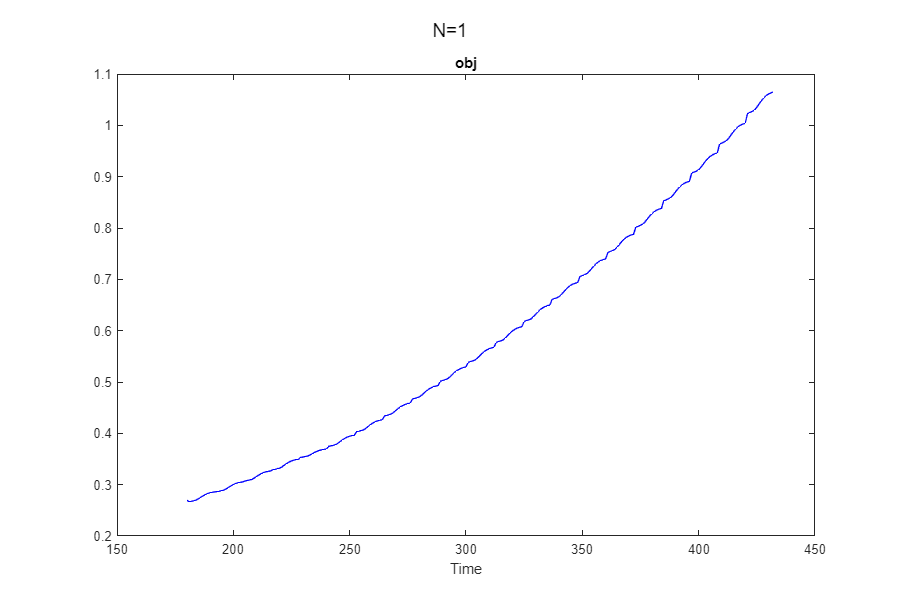

figure(1)
clf
T.Properties.CustomProperties.output=[67];
ydat2=gsua_eval(T.Nominal,T,180:432);

Tua=T;
Tua.Range=[T.Nominal*0.5,T.Nominal*1.5];
Tua.Range(3,1:2)=[0, 0.05];
Tua.Range(27:38,1:2)=[T.Nominal(27:38),T.Nominal(27:38)]

Tua = 56×2 table
                     Range           Nominal
               __________________    _______

    trans1         0.1        0.3       0.2 
    trans2         0.1        0.3       0.2 
    impr             0       0.05         0 
    Cdf1        0.0711     0.2133    0.1422 
    Cdf2       0.12625    0.37875    0.2525 
    Cdf3       0.17445    0.52335    0.3489 
    Ctr1f1       0.098      0.294     0.196 
    Ctr2f1        0.13       0.39      0.26 
    Ctr1f2       0.098      0.294     0.196 
    Ctr2f2        0.13       0.39      0.26 
    Ctr1f3       0.098      0.294     0.196 
    Ctr2f3        0.13       0.39      0.26 
    Ctr1f4       0.098      0.294     0.196 
    Ctr2f4

[M,TuaS]=gsua_dmatrix(Tua,1000);

Tua_sa=gsua_sa(M,TuaS);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 8).
Progress: 3%
Estimated processing time (h:m:s): 0:28:44
Remaining time (h:m:s): 0:28:6
Elapsed time (h:m:s): 0:0:38
Estimated stop time (h:m:s): 3:52:34
Number of simulations: 22500
Progress: 5%
Estimated processing time (h:m:s): 0:15:3
Remaining time (h:m:s): 0:14:22
Elapsed time (h:m:s): 0:0:40
Estimated stop time (h:m:s): 3:38:52
Number of simulations: 22500
Progress: 7%
Estimated processing time (h:m:s): 0:10:29
Remaining time (h:m:s): 0:9:47
Elapsed time (h:m:s): 0:0:41
Estimated stop time (h:m:s): 3:34:19
Number of simulations: 22500
Progress: 9%
Estimated processing time (h:m:s): 0:8:12
Remaining time (h:m:s): 0:7:28
Elapsed time (h:m:s): 0:0:43
Estimated stop time (h:m:s): 3:32:1
Number of simulations: 22500
Progress: 12%
Estimated processing time (h:m:s): 0:6:50
Remaining time (h:m:s): 0:6:4
Elapsed time (h:m:s): 0:0:45
Estimated stop time (h:m:s): 3:30:40
Numb

sum(Tua_sa.Si)/sum(abs(Tua_sa.Si))

ans = 0.9454

Tua_sa.Properties.RowNames

ans = 56×1 cell array
    {'trans1' }
    {'trans2' }
    {'impr'   }
    {'Cdf1'   }
    {'Cdf2'   }
    {'Cdf3'   }
    {'Ctr1f1' }
    {'Ctr2f1' }
    {'Ctr1f2' }
    {'Ctr2f2' }
    {'Ctr1f3' }
    {'Ctr2f3' }
    {'Ctr1f4' }
    {'Ctr2f4' }
    {'CefT1f1'}
    {'CefT2f1'}
    {'CefT3f1'}
    {'CefT1f2'}
    {'CefT2f2'}
    {'CefT3f2'}
    {'CefT1f3'}
    {'CefT2f3'}
    {'CefT3f3'}
    {'CefT1f4'}
    {'CefT2f4'}
    {'CefT3f4'}
    {'CcsT1f1'}
    {'CcsT2f1'}
    {'CcsT3f1'}
    {'CcsT1f2'}


Tua_sa.Properties.RowNames{1}='\beta_1';
Tua_sa.Properties.RowNames{2}='\beta_2';
Tua_sa.Properties.RowNames{3}='\eta';
Tua_sa.Properties.RowNames{4}='\delta[s_1]';
Tua_sa.Properties.RowNames{5}='\delta[s_2]';
Tua_sa.Properties.RowNames{6}='\delta[s_3]';
Tua_sa.Properties.RowNames{7}='\lambda[s_1T_1]';
Tua_sa.Properties.RowNames{8}='\lambda[s_1T_2]';
Tua_sa.Properties.RowNames{9}='\lambda[s_2T_1]';
Tua_sa.Properties.RowNames{10}='\lambda[s_2T_2]';
Tua_sa.Properties.RowNames{11}='\lambda[s_3T_1]';
Tua_sa.Properties.RowNames{12}='\lambda[s_3T_2]';
Tua_sa.Properties.RowNames{13}='\lambda[s_4T_1]';
Tua_sa.Properties.RowNames{14}='\lambda[s_4T_2]';
Tua_sa.Properties.RowNames{15}='\gamma[s_1T_1]';
Tua_sa.Properties.RowNames{16}='\gamma[s_1T_2]';
Tua_sa.Properties.RowNames{17}='\gamma[s_1T_3]';
Tua_sa.Properties.RowNames{18}='\gamma[s_2T_1]';
Tua_sa.Properties.RowNames{19}='\gamma[s_2T_2]';
Tua_sa.Properties.RowNames{20}='\gamma[s_2T_3]';
Tua_sa.Properties.RowNames{21}='\gamma[s_3T_1]';
Tua_sa.Properties.RowNames{22}='\gamma[s_3T_2]';
Tua_sa.Properties.RowNames{23}='\gamma[s_3T_3]';
Tua_sa.Properties.RowNames{24}='\gamma[s_4T_1]';
Tua_sa.Properties.RowNames{25}='\gamma[s_4T_2]';
Tua_sa.Properties.RowNames{26}='\gamma[s_4T_3]';
Tua_sa.Properties.RowNames{27}='C[s_1T_1]';
Tua_sa.Properties.RowNames{28}='C[s_1T_2]';
Tua_sa.Properties.RowNames{29}='C[s_1T_3]';
Tua_sa.Properties.RowNames{30}='C[s_2T_1]';
Tua_sa.Properties.RowNames{31}='C[s_2T_2]';
Tua_sa.Properties.RowNames{32}='C[s_2T_3]';
Tua_sa.Properties.RowNames{33}='C[s_3T_1]';
Tua_sa.Properties.RowNames{34}='C[s_3T_2]';
Tua_sa.Properties.RowNames{35}='C[s_3T_3]';
Tua_sa.Properties.RowNames{36}='C[s_4T_1]';
Tua_sa.Properties.RowNames{37}='C[s_4T_2]';
Tua_sa.Properties.RowNames{38}='C[s_4T_3]';
Tua_sa.Properties.RowNames{39}='\alpha[s_1T_1]';
Tua_sa.Properties.RowNames{40}='\alpha[s_2T_1]';
Tua_sa.Properties.RowNames{41}='\alpha[s_3T_1]';
Tua_sa.Properties.RowNames{42}='\alpha[s_4T_1]';
Tua_sa.Properties.RowNames{43}='\alpha[s_1T_2]';
Tua_sa.Properties.RowNames{44}='\alpha[s_2T_2]';
Tua_sa.Properties.RowNames{45}='\alpha[s_3T_2]';
Tua_sa.Properties.RowNames{46}='\alpha[s_4T_2]';
Tua_sa.Properties.RowNames{47}='\alpha[s_1T_3]';
Tua_sa.Properties.RowNames{48}='\alpha[s_2T_3]';
Tua_sa.Properties.RowNames{49}='\alpha[s_3T_3]';
Tua_sa.Properties.RowNames{50}='\alpha[s_4T_3]';
Tua_sa.Properties.RowNames{51}='\alpha[s_1]';
Tua_sa.Properties.RowNames{52}='\alpha[s_2]';
Tua_sa.Properties.RowNames{53}='\alpha[s_3]';
Tua_sa.Properties.RowNames{54}='C[\delta_0]';
Tua_sa.Properties.RowNames{55}='\delta[s_0]';
Tua_sa.Properties.RowNames{56}='C[\eta]';

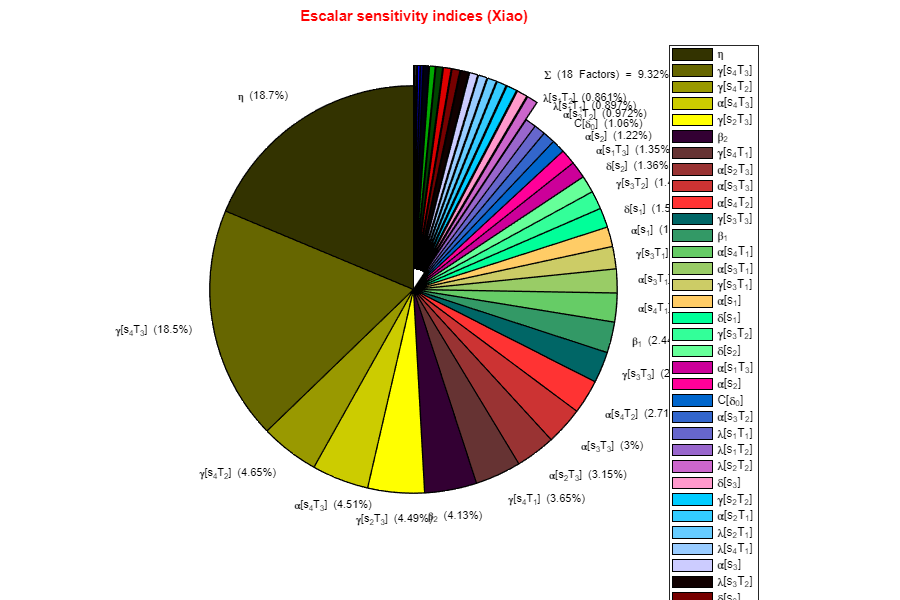

figure(2)
clf
gsua_plot('Pie',Tua_sa,Tua_sa.STi);

sorter=Tua_sa.STi/sum(Tua_sa.STi);
[sorter2,sind]=sort(sorter,'descend');
Tua_sa.SSTi=sorter;
%writetable(Tua_sa(sind,{'Range','Nominal','SSTi'}),'SAPaper.xls','WriteRowNames',true)

# Uncertainty analysis

Tua_sa2=Tua_sa;
Tua_sa2.Range(sind(24:end),:)=[T.Nominal(sind(24:end)), T.Nominal(sind(24:end))];
[M2,Tua_sa2]=gsua_dmatrix(Tua_sa2,5e3);

Progress: 100%
Estimated processing time (h:m:s): 0:2:34
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:2:34
Estimated stop time (h:m:s): 3:28:20
Number of simulations: 5000


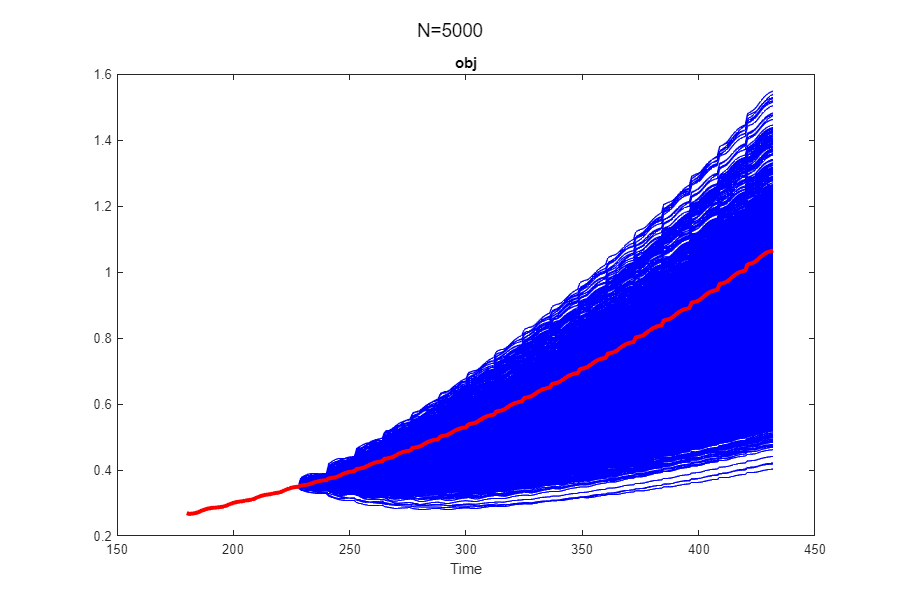

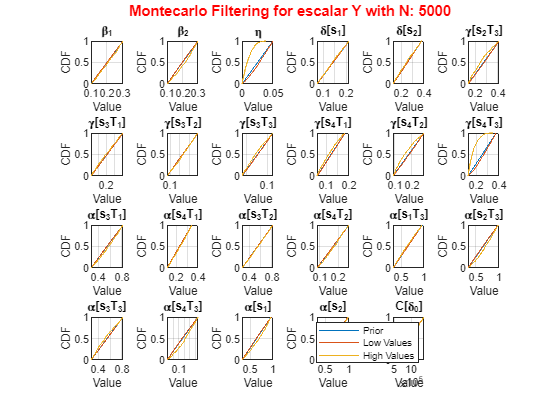

yua=gsua_ua(M2,Tua_sa2,'parallel',false,'ynom',ydat2,'xdata',180:432);